# Offline RL for GBWM — Week 5 v2: Tighter Stress Gate

Only change over week5_regime_reward.m (v1): VIX_THR 1.0 -> 1.5 (v1 triggered on 31% of train days — too broad) SLOPE_THR -1.0 -> -1.5 (same reason) logsRoot week5_regime_reward -> week5_regime_reward_v2 Lambda kept at 2.5 to isolate the threshold effect. Target: train stress rate ~15% (was 31.1%), so the gate becomes a sparse "real crisis" signal instead of a global loss-aversion shift.

v1 result recap: Mean Sharpe 0.25->0.37 BUT MaxDD P90 12.87%->14.40% and worst Sharpe -5.78->-5.57 — tail risk did not improve, action distribution went bimodal (action 2: 23% + action 15: 17%). Suspected cause: gate too loose -> global loss-aversion, not a regime-specific signal.

Original v1 spec: Only change over week4_macro_state_v3.m: Reward in episode generation is amplified by lambda when the step is taken inside a "stress" macro regime AND the realized return is negative.

Rationale (mentor suggestion + literature): - Moody & Saffell 1998: incremental risk-adjusted reward - Risk-Sensitive DRL for Portfolio Optimization (MDPI JRFM 2025): "risk-neutral RL is not enough" — encode drawdown / loss-aversion in reward - Adaptive Regime-Aware RL (arXiv 2509.14385): explicit stress conditioning - Behaviorally informed DRL (Nature SR 2026): loss aversion lambda in [2.0, 2.5]

Everything else (state dim, network, agent, eval windows, seeds) IDENTICAL to v3.

clear; clc;

## Fixed Parameters (copied from v3)

initialWealth   = 100000;
goalWealth      = 102000;
contribution    = 0;
rebalanceStep   = calmonths(1);

trainingRange   = 2515;
horizonPeriods  = 30;
numEpisodes     = 165;
numActions      = 15;

logsRoot        = fullfile("experiments", "logs", "week5_regime_reward_v2");

hiddenUnits     = 32;
maxEpochs       = 100;
stepsPerEpoch   = 400;
miniBatchSize   = 256;
discountFactor  = 0.995;

seeds           = [1000 2000 3000 4000 5000];
nSeeds          = numel(seeds);

numEvalEpisodes = 30;
evalStepSize    = 30;

% NEW — regime-gated reward params
VIX_THR    = 1.5;    % was 1.0 in v1 — tighter, target train stress rate ~15%
SLOPE_THR  = -1.5;   % was -1.0 in v1 — tighter, target train stress rate ~15%
LAMBDA     = 2.5;    % unchanged — isolate threshold effect

## Load price data

pricesTT   = readtable("data/prices_train.csv");
assetNames = pricesTT.Properties.VariableNames(2:end);
P_train    = pricesTT{:, 2:end};
R_train    = diff(log(P_train));

R_sub = R_train(1:trainingRange, :);
mu    = mean(R_sub, 1)';
Sigma = cov(R_sub);

p = Portfolio("AssetList", assetNames);
p = setDefaultConstraints(p);
p = setAssetMoments(p, mu, Sigma);
W_frontier = estimateFrontier(p, numActions);

## Load macro data, z-score on train

macroTT   = readtable("data/macro_train.csv");
M_train   = macroTT{:, 2:end};                  % columns: DGS10 T10Y2Y VIXCLS DFF
macroMean = mean(M_train, 1);
macroStd  = std(M_train, 0, 1);
macroStd(macroStd == 0) = 1;
M_train_z = (M_train - macroMean) ./ macroStd;

% Column indices in z-scored macro (used by stress gate)
IDX_SLOPE = 2;   % T10Y2Y_z
IDX_VIX   = 3;   % VIXCLS_z

% Stress-rate diagnostic on train segment
stressMask_train = (M_train_z(1:trainingRange, IDX_VIX)   > VIX_THR) | ...
                   (M_train_z(1:trainingRange, IDX_SLOPE) < SLOPE_THR);
fprintf("Train stress rate: %.1f%% (%d / %d days)\n", ...
    100*mean(stressMask_train), sum(stressMask_train), trainingRange);

Train stress rate: 17.4% (437 / 2515 days)


## Load + z-score test data

[R_full, M_test_z] = inputTestData('data/prices_test.csv', 'data/macro_test.csv', ...
                                    macroMean, macroStd);
stressMask_test = (M_test_z(:, IDX_VIX)   > VIX_THR) | ...
                  (M_test_z(:, IDX_SLOPE) < SLOPE_THR);
fprintf("Test  stress rate: %.1f%% (%d / %d days)\n\n", ...
    100*mean(stressMask_test), sum(stressMask_test), size(M_test_z,1));

Test  stress rate: 73.8% (740 / 1003 days)



## Cross-seed result storage

results = struct();
results.successRate     = nan(nSeeds, 1);
results.meanSharpe      = nan(nSeeds, 1);
results.stdSharpe       = nan(nSeeds, 1);
results.meanMaxDD       = nan(nSeeds, 1);
results.stdMaxDD        = nan(nSeeds, 1);
results.meanTermWealth  = nan(nSeeds, 1);
results.p10TermWealth   = nan(nSeeds, 1);
results.p90TermWealth   = nan(nSeeds, 1);
results.minSharpe       = nan(nSeeds, 1);
results.p90MaxDD        = nan(nSeeds, 1);
results.actionHist      = zeros(nSeeds, numActions);
results.stressActionHist = zeros(nSeeds, numActions);   % action use only on stress days

allWealthPathsBySeed = cell(nSeeds, 1);

normalizeWealth = @(w) min(w/goalWealth, 5);
timeFrac        = @(t) t / horizonPeriods;

obsDim = 2 + size(M_train_z, 2);

## Loop over seeds

for sIdx = 1:nSeeds
    seed = seeds(sIdx);
    rng(seed, "twister");

    fprintf("\n========== Seed %d (%d/%d) ==========\n", seed, sIdx, nSeeds);

    seedLogsFolder = fullfile(logsRoot, sprintf("seed_%d", seed));
    if isfolder(seedLogsFolder)
        delete(fullfile(seedLogsFolder, "*.mat"));
    else
        mkdir(seedLogsFolder);
    end

    % --- Build offline episodes with regime-gated reward ---
    episodeCount  = 0;
    startIdx      = 1;
    stepSize      = floor(horizonPeriods/2);
    nStressSteps  = 0;
    nAmplified    = 0;

    while episodeCount < numEpisodes && (startIdx + horizonPeriods - 1) <= size(R_sub,1)
        episodeCount = episodeCount + 1;
        expStruct = repmat(struct("Observation",[],"Action",[],"Reward",[], ...
            "NextObservation",[],"IsDone",[]), horizonPeriods, 1);

        wealth = initialWealth;
        for t = 1:horizonPeriods
            dayIdx   = startIdx + t - 1;
            macroVec = M_train_z(dayIdx, :)';
            obs      = [normalizeWealth(wealth); timeFrac(t); macroVec];

            aIdx = randi(numActions);
            w    = W_frontier(:, aIdx);

            r_tp1      = R_sub(dayIdx, :) * w;
            wealthNext = (wealth + contribution) * (1 + r_tp1);

            r_raw    = log(wealthNext / wealth);
            isStress = (macroVec(IDX_VIX) > VIX_THR) || (macroVec(IDX_SLOPE) < SLOPE_THR);

            if isStress
                nStressSteps = nStressSteps + 1;
            end
            if isStress && r_raw < 0
                reward      = LAMBDA * r_raw;
                nAmplified  = nAmplified + 1;
            else
                reward = r_raw;
            end
            if t == horizonPeriods && wealthNext >= goalWealth
                reward = reward + 1.0;
            end

            nextDayIdx   = min(dayIdx + 1, size(M_train_z, 1));
            nextMacroVec = M_train_z(nextDayIdx, :)';
            nextObs      = [normalizeWealth(wealthNext); ...
                            timeFrac(min(t+1, horizonPeriods)); ...
                            nextMacroVec];
            isDone       = (t == horizonPeriods);

            expStruct(t).Observation     = {obs};
            expStruct(t).Action          = {aIdx};
            expStruct(t).Reward          = reward;
            expStruct(t).NextObservation = {nextObs};
            expStruct(t).IsDone          = isDone;

            wealth = wealthNext;
        end

        epFile = fullfile(seedLogsFolder, sprintf("loggedData%03d.mat", episodeCount));
        exp = expStruct;
        save(epFile, "exp");
        startIdx = startIdx + stepSize;
    end

    totalSteps = episodeCount * horizonPeriods;
    fprintf("  Saved %d episodes (%d transitions). Stress steps: %d (%.1f%%). Amplified-loss steps: %d (%.1f%%)\n", ...
        episodeCount, totalSteps, nStressSteps, 100*nStressSteps/totalSteps, ...
        nAmplified, 100*nAmplified/totalSteps);

    % --- File datastore ---
    myReadFcn = @(fname) load(fname, "exp").exp;
    fds = fileDatastore(fullfile(seedLogsFolder, "loggedData*.mat"), ...
                        "ReadFcn", myReadFcn);

    % --- Build fresh agent ---
    obsInfo = rlNumericSpec([obsDim 1], Name="GBWMObservation");
    actInfo = rlFiniteSetSpec(1:numActions, Name="AllocationIndex");

    criticLG = layerGraph([
        featureInputLayer(obsInfo.Dimension(1), Name="state")
        fullyConnectedLayer(hiddenUnits)
        reluLayer
        fullyConnectedLayer(hiddenUnits)
        reluLayer
        fullyConnectedLayer(numActions, Name="Qout")
        ]);

    criticNet = dlnetwork(criticLG);
    critic    = rlVectorQValueFunction(criticNet, obsInfo, actInfo);

    agentOpts = rlDQNAgentOptions( ...
        DiscountFactor=discountFactor, ...
        ExperienceBufferLength=1e6, ...
        MiniBatchSize=miniBatchSize, ...
        TargetUpdateMethod="periodic", ...
        TargetUpdateFrequency=4, ...
        UseDoubleDQN=true);
    agentOpts.CriticOptimizerOptions.LearnRate         = 5e-4;
    agentOpts.CriticOptimizerOptions.GradientThreshold = 1;
    agent = rlDQNAgent(critic, agentOpts);

    % --- Train ---
    tfdOpts = rlTrainingFromDataOptions( ...
        MaxEpochs        = maxEpochs, ...
        NumStepsPerEpoch = stepsPerEpoch, ...
        Plots            = "none", ...
        Verbose          = false);
    trainFromData(agent, fds, tfdOpts);
    save(fullfile(seedLogsFolder, "TrainedAgent.mat"), "agent");

    % --- Hold-out evaluation (raw wealth, no reward shaping) ---
    successCount   = 0;
    allSharpes     = nan(numEvalEpisodes, 1);
    allMaxDD       = nan(numEvalEpisodes, 1);
    allTermWealth  = nan(numEvalEpisodes, 1);
    allWealthPaths = cell(numEvalEpisodes, 1);
    allActions     = zeros(numEvalEpisodes, horizonPeriods);
    allStressFlags = false(numEvalEpisodes, horizonPeriods);

    for ep = 1:numEvalEpisodes
        startEval = (ep-1)*evalStepSize + 1;
        if startEval + horizonPeriods - 1 > size(R_full, 1)
            break;
        end

        wealth = zeros(horizonPeriods+1, 1);
        wealth(1) = initialWealth;
        chosenActions = zeros(1, horizonPeriods);
        stressFlags   = false(1, horizonPeriods);
        for t = 1:horizonPeriods
            dayIdx   = startEval + t - 1;
            macroVec = M_test_z(dayIdx, :)';
            obs      = { [normalizeWealth(wealth(t)); timeFrac(t); macroVec] };
            aGreedy  = agent.getAction(obs);
            chosenActions(t) = aGreedy{1};
            stressFlags(t)   = (macroVec(IDX_VIX) > VIX_THR) || (macroVec(IDX_SLOPE) < SLOPE_THR);
            w        = W_frontier(:, aGreedy{1});
            r_tp1    = R_full(dayIdx, :) * w;
            wealth(t+1) = (wealth(t) + contribution) * (1 + r_tp1);
        end

        rets    = diff(log(wealth));
        sharpe  = mean(rets) / std(rets) * sqrt(252);
        maxDD   = max(cummax(wealth) - wealth) / max(wealth);

        allSharpes(ep)     = sharpe;
        allMaxDD(ep)       = maxDD;
        allTermWealth(ep)  = wealth(end);
        allWealthPaths{ep} = wealth;
        allActions(ep, :)  = chosenActions;
        allStressFlags(ep, :) = stressFlags;
        successCount       = successCount + double(wealth(end) >= goalWealth);
    end

    results.successRate(sIdx)    = successCount;
    results.meanSharpe(sIdx)     = mean(allSharpes,'omitnan');
    results.stdSharpe(sIdx)      = std(allSharpes,'omitnan');
    results.meanMaxDD(sIdx)      = mean(allMaxDD,'omitnan');
    results.stdMaxDD(sIdx)       = std(allMaxDD,'omitnan');
    results.meanTermWealth(sIdx) = mean(allTermWealth,'omitnan');
    results.p10TermWealth(sIdx)  = prctile(allTermWealth, 10);
    results.p90TermWealth(sIdx)  = prctile(allTermWealth, 90);
    results.minSharpe(sIdx)      = min(allSharpes);
    results.p90MaxDD(sIdx)       = prctile(allMaxDD, 90);
    for a = 1:numActions
        results.actionHist(sIdx, a)       = sum(allActions(:) == a);
        results.stressActionHist(sIdx, a) = sum(allActions(allStressFlags) == a);
    end

    allWealthPathsBySeed{sIdx} = allWealthPaths;

    fprintf("  Success %d/%d | Sharpe %.2f±%.2f | MaxDD %.2f%%±%.2f%% | TermW %.0f (P10 %.0f)\n", ...
        successCount, numEvalEpisodes, ...
        results.meanSharpe(sIdx), results.stdSharpe(sIdx), ...
        results.meanMaxDD(sIdx)*100, results.stdMaxDD(sIdx)*100, ...
        results.meanTermWealth(sIdx), results.p10TermWealth(sIdx));
end


========== Seed 1000 (1/5) ==========


  Saved 165 episodes (4950 transitions). Stress steps: 835 (16.9%). Amplified-loss steps: 359 (7.3%)


  Success 9/30 | Sharpe 0.01±2.88 | MaxDD 8.58%±8.58% | TermW 98109 (P10 90160)



========== Seed 2000 (2/5) ==========


  Saved 165 episodes (4950 transitions). Stress steps: 835 (16.9%). Amplified-loss steps: 349 (7.1%)


  Success 10/30 | Sharpe 0.28±2.77 | MaxDD 5.54%±3.88% | TermW 100146 (P10 93194)



========== Seed 3000 (3/5) ==========


  Saved 165 episodes (4950 transitions). Stress steps: 835 (16.9%). Amplified-loss steps: 360 (7.3%)


  Success 16/30 | Sharpe 1.03±3.14 | MaxDD 11.57%±6.44% | TermW 105452 (P10 86787)



========== Seed 4000 (4/5) ==========


  Saved 165 episodes (4950 transitions). Stress steps: 835 (16.9%). Amplified-loss steps: 355 (7.2%)


  Success 16/30 | Sharpe 0.56±3.04 | MaxDD 6.03%±3.56% | TermW 101441 (P10 92063)



========== Seed 5000 (5/5) ==========


  Saved 165 episodes (4950 transitions). Stress steps: 835 (16.9%). Amplified-loss steps: 376 (7.6%)


  Success 14/30 | Sharpe 0.63±2.56 | MaxDD 6.77%±3.78% | TermW 101956 (P10 91416)


## Cross-seed summary

fprintf("\n\n===== Cross-seed summary (n=%d seeds) — Week 5 regime-gated reward =====\n", nSeeds);



===== Cross-seed summary (n=5 seeds) — Week 5 regime-gated reward =====


fprintf("Stress gate          : VIX_z > %.2f  OR  T10Y2Y_z < %.2f   |   LAMBDA = %.2f\n", ...
    VIX_THR, SLOPE_THR, LAMBDA);

Stress gate          : VIX_z > 1.50  OR  T10Y2Y_z < -1.50   |   LAMBDA = 2.50


fprintf("Success rate         : %.1f / %d  (std %.2f)\n", ...
    mean(results.successRate), numEvalEpisodes, std(results.successRate));

Success rate         : 13.0 / 30  (std 3.32)


fprintf("Mean Sharpe          : %.2f (across-seed std %.2f)\n", ...
    mean(results.meanSharpe), std(results.meanSharpe));

Mean Sharpe          : 0.50 (across-seed std 0.38)


fprintf("Within-seed Sharpe std : %.2f (avg)\n", mean(results.stdSharpe));

Within-seed Sharpe std : 2.88 (avg)


fprintf("Mean MaxDD           : %.2f%% (across-seed std %.2f%%)\n", ...
    mean(results.meanMaxDD)*100, std(results.meanMaxDD)*100);

Mean MaxDD           : 7.70% (across-seed std 2.46%)


fprintf("Mean Terminal Wealth : %.0f (across-seed std %.0f)\n", ...
    mean(results.meanTermWealth), std(results.meanTermWealth));

Mean Terminal Wealth : 101421 (across-seed std 2698)


fprintf("Terminal P10 (avg)   : %.0f\n", mean(results.p10TermWealth));

Terminal P10 (avg)   : 90724


fprintf("Worst Sharpe (avg)   : %.2f   <-- v3: -5.78 | v1: -5.57\n", mean(results.minSharpe));

Worst Sharpe (avg)   : -5.80   <-- v3: -5.78 | v1: -5.57


fprintf("MaxDD P90 (avg)      : %.2f%% <-- v3: 12.87%% | v1: 14.40%%\n", mean(results.p90MaxDD)*100);

MaxDD P90 (avg)      : 15.41% <-- v3: 12.87% | v1: 14.40%



fprintf("\n--- Per-seed table ---\n");


--- Per-seed table ---


fprintf("seed | succ | Sharpe(mean±std) | MaxDD(mean±std)  | TermW(mean / P10)\n");

seed | succ | Sharpe(mean±std) | MaxDD(mean±std)  | TermW(mean / P10)


for sIdx = 1:nSeeds
    fprintf("%4d | %4d | %5.2f ± %4.2f    | %5.2f%% ± %4.2f%%  | %.0f / %.0f\n", ...
        seeds(sIdx), results.successRate(sIdx), ...
        results.meanSharpe(sIdx), results.stdSharpe(sIdx), ...
        results.meanMaxDD(sIdx)*100, results.stdMaxDD(sIdx)*100, ...
        results.meanTermWealth(sIdx), results.p10TermWealth(sIdx));
end

1000 |    9 |  0.01 ± 2.88    |  8.58% ± 8.58%  | 98109 / 90160
2000 |   10 |  0.28 ± 2.77    |  5.54% ± 3.88%  | 100146 / 93194
3000 |   16 |  1.03 ± 3.14    | 11.57% ± 6.44%  | 105452 / 86787
4000 |   16 |  0.56 ± 3.04    |  6.03% ± 3.56%  | 101441 / 92063
5000 |   14 |  0.63 ± 2.56    |  6.77% ± 3.78%  | 101956 / 91416



fprintf("\n--- Action histogram (all eval steps) ---\n");


--- Action histogram (all eval steps) ---


totalHist = sum(results.actionHist, 1);
totalSteps = sum(totalHist);
for a = 1:numActions
    if totalHist(a) > 0
        fprintf("  action %2d : %4d (%.1f%%)\n", a, totalHist(a), 100*totalHist(a)/totalSteps);
    end
end

  action  1 :   69 (1.5%)
  action  2 :  176 (3.9%)
  action  3 :   57 (1.3%)
  action  4 :   20 (0.4%)
  action  5 :   22 (0.5%)
  action  6 :  650 (14.4%)
  action  7 :  444 (9.9%)
  action  8 :   52 (1.2%)
  action  9 :  157 (3.5%)
  action 10 :  267 (5.9%)
  action 11 :   45 (1.0%)
  action 12 : 1092 (24.3%)
  action 13 :  165 (3.7%)
  action 14 :  338 (7.5%)
  action 15 :  946 (21.0%)



fprintf("\n--- Action histogram (STRESS days only) ---\n");


--- Action histogram (STRESS days only) ---


stressHist = sum(results.stressActionHist, 1);
stressTotal = sum(stressHist);
if stressTotal > 0
    for a = 1:numActions
        if stressHist(a) > 0
            fprintf("  action %2d : %4d (%.1f%%)\n", a, stressHist(a), 100*stressHist(a)/stressTotal);
        end
    end
else
    fprintf("  (no stress days flagged in test set)\n");
end

  action  1 :   62 (1.7%)
  action  2 :  110 (3.0%)
  action  3 :   39 (1.1%)
  action  4 :   20 (0.5%)
  action  5 :   22 (0.6%)
  action  6 :  521 (14.1%)
  action  7 :  402 (10.9%)
  action  8 :   42 (1.1%)
  action  9 :  136 (3.7%)
  action 10 :  227 (6.2%)
  action 11 :   36 (1.0%)
  action 12 :  869 (23.6%)
  action 13 :  142 (3.8%)
  action 14 :  270 (7.3%)
  action 15 :  792 (21.5%)


## Plot — aggregated wealth band across all seeds

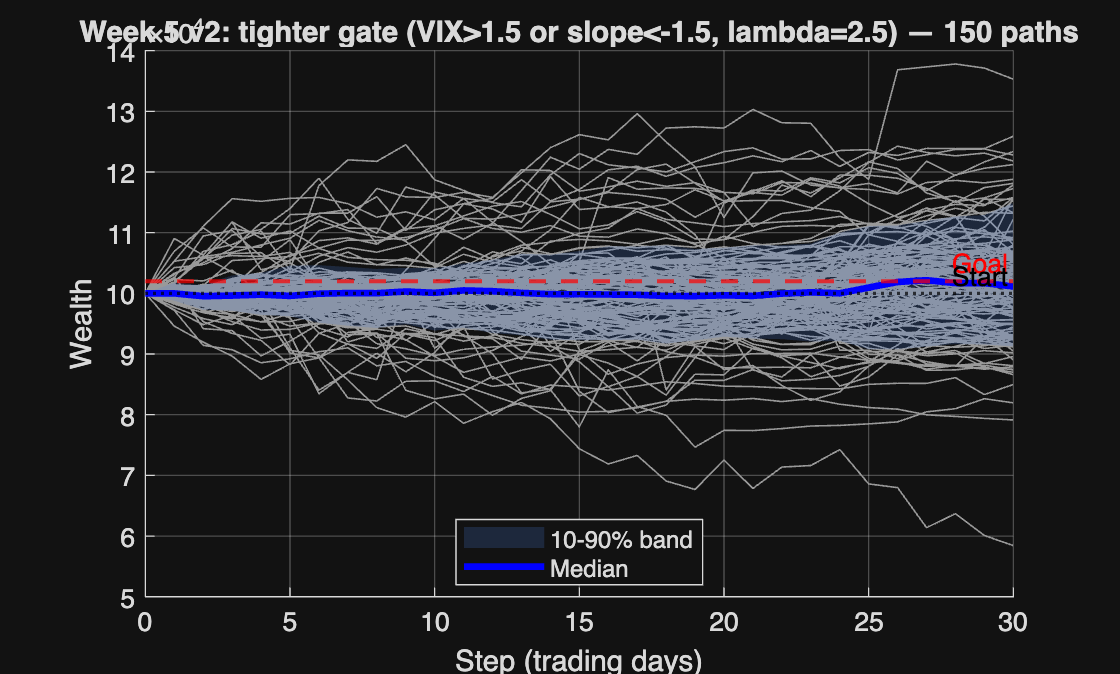

figure('Name','Hold-out wealth paths (Week 5 regime-gated reward)');
hold on;

allPathsFlat = nan(nSeeds * numEvalEpisodes, horizonPeriods + 1);
rowCursor = 0;
for sIdx = 1:nSeeds
    paths = allWealthPathsBySeed{sIdx};
    for ep = 1:numel(paths)
        if ~isempty(paths{ep})
            rowCursor = rowCursor + 1;
            allPathsFlat(rowCursor, :) = paths{ep}';
        end
    end
end
allPathsFlat = allPathsFlat(1:rowCursor, :);

steps = 0:horizonPeriods;

for r = 1:size(allPathsFlat, 1)
    plot(steps, allPathsFlat(r, :), 'Color', [0.6 0.6 0.6 0.15], ...
        'LineWidth', 0.6, 'HandleVisibility', 'off');
end

p10 = prctile(allPathsFlat, 10, 1);
p90 = prctile(allPathsFlat, 90, 1);
fill([steps, fliplr(steps)], [p10, fliplr(p90)], [0.3 0.5 0.9], ...
    'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', '10-90% band');
plot(steps, median(allPathsFlat, 1, 'omitnan'), 'b-', 'LineWidth', 2.5, ...
    'DisplayName', 'Median');

yline(goalWealth, '--r', 'Goal', 'LineWidth', 1.5, 'HandleVisibility', 'off');
yline(initialWealth, ':k', 'Start', 'LineWidth', 1.2, 'HandleVisibility', 'off');

xlabel('Step (trading days)');
ylabel('Wealth');
title(sprintf('Week 5 v2: tighter gate (VIX>%.1f or slope<%.1f, lambda=%.1f) — %d paths', ...
    VIX_THR, SLOPE_THR, LAMBDA, rowCursor));
legend('Location','best');
grid on;

## Local Functions

function [R, M_z] = inputTestData(priceFile, macroFile, macroMean, macroStd)
    pricesTT = readtable(priceFile, 'VariableNamingRule', 'preserve');
    P = pricesTT{:, 2:end};
    R = diff(log(P));

    macroTT = readtable(macroFile, 'VariableNamingRule', 'preserve');
    M = macroTT{:, 2:end};
    M_z = (M - macroMean) ./ macroStd;
end